# UACS : Guide de l'utilisateur

## Simulation statique d'un circuit linéaire

### Pont diviseur de tension

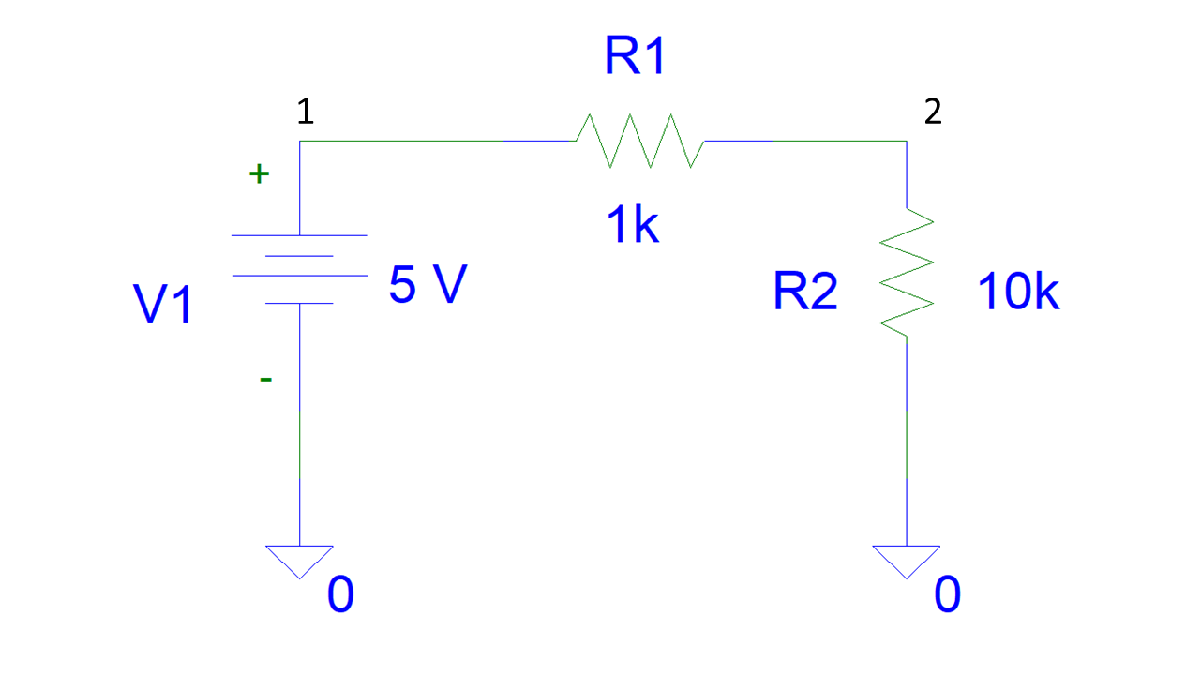

Définition du circuit :

clear
netlist={
    'R1 1 2 1e3'
    'R2 2 0 10e3'
    'V1 1 0 5'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09, dt0=1e-12
2 Resistor(s), 0 Inductor(s), 0 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}

uacs renvoie une structure sim avec sim.X correspondant au vecteur des inconnues de la formulation MNA : les potentiels des noeuds puis les inconnues de courant de la source de tension, dans l'ordre de in.V (si plusieurs sources). La *cell* sim.names donne la composition du vecteur des inconnues sim.X.

fprintf('Potentiel du noeud 1 : %g V\nPotentiel du noeud 2 : %g V\nCourant débité par la source de tension : %g A\n',sim.X(1),sim.X(2),sim.X(3))

Potentiel du noeud 1 : 5 V
Potentiel du noeud 2 : 4.54545 V
Courant débité par la source de tension : -0.000454545 A


### Circuit RC (simulation statique)

En simulation statique, la capacité est équivalente à un circuit ouvert.

clear
netlist={
    'R1 1 2 1e3'
    'C1 2 0 1e-9'
    'V1 1 0 5'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}

sim.X

ans =     5.0000
    5.0000
   -0.0000


## Simulation temporelle d'un circuit linéaire

### Circuit RC, conditions initiales nulles

clear in
netlist={
    'R1 1 2 1e3'
    'C1 2 0 100e-9'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

118 time steps computed in 0.0935894 seconds.


sim = struct with fields:
           X_t: [3×118 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 4.0040e-09 8.0040e-09 1.6004e-08 3.2004e-08 6.4004e-08 1.2800e-07 2.5600e-07 5.1200e-07 1.0240e-06 2.0480e-06 4.0960e-06 8.1920e-06 1.6384e-05 2.6384e-05 3.6384e-05 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}

   initTRAN=CI force la condition initiale à 0 (sauf pour les capacités si une tension initiale est définie par IC=... ) pour t=0. Sinon la condition initiale = Point de fonctionnement (par défaut initTRAN=OP).

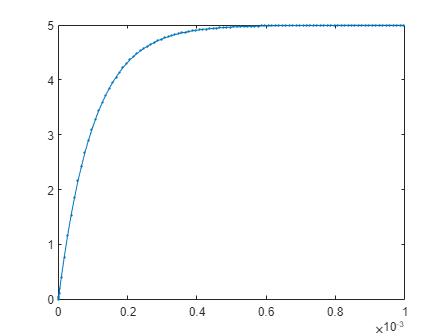

plot(sim.t,sim.X_t(2,:),'.-')

### Circuit RC conditions Vc(0)= 2 V

netlist={
    'R1 1 2 1e3'
    'C1 2 0 100e-9 IC=2'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

117 time steps computed in 0.0340006 seconds.


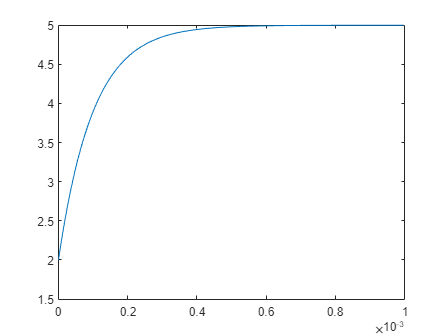

plot(sim.t,sim.X_t(2,:))

### Circuit RC-RC

clear
netlist={
    'R1 1 2 1000'
    'R2 2 0 10e3'
    'C1 2 0 100e-9'
    'C2 1 2 10e-9'
    'V1 1 0 5'
    '.tran tstop=1e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
2 Resistor(s), 0 Inductor(s), 2 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.000999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

117 time steps computed in 0.0907719 seconds.


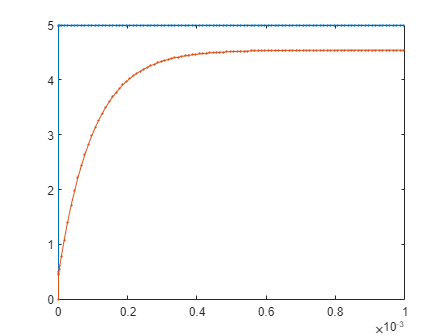

plot(sim.t,sim.X_t([1 2],:),'.-')

### Circuit RLC

clear
netlist={
    'R1 1 2 220'
    'L1 2 3 0.1 IC=0'
    'C1 3 0 10e-9 IC=0'
    'V1 1 0 1'
    '.tran tstop=5e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist);

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 1 Inductor(s), 1 Capacitor(s), 0 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 3 electrical node(s)
Transient Simulation, t0=0, tmax=0.00499987, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

616 time steps computed in 0.170277 seconds.


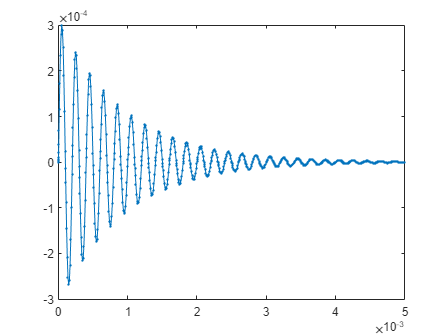

plot(sim.t,-sim.X_t(end,:),'.-')

Analyse symbolique du circuit RLC

netlist={
    'R1 1 2 220'
    'L1 2 3 0.1'
    'C1 3 0 10e-9'
    'V1 1 0 Ve'
    '.symb'
    };
sim1=uacs(netlist)

*** Analyse symbolique du Circuit ***
** fspice 2.43  ** (c) Frederic Martinez


sim1 = struct with fields:
       X: [4×1 sym]
    name: {'V(1)'  'V(2)'  'V(3)'  'I(V1)'}

Fonction de transfert :

H=sim1.X(3)/sim1.X(1)

$$H = \frac{1000000000}{s^{2}+2200\,s+1000000000}$$

Expression symbolique de la réponse indicielle :

syms s
vs=simplify(ilaplace(H/s))

$$vs = 1-{\mathrm{e}}^{-1100\,t}\,\left(\cos\left(1300\,\sqrt{591}\,t\right)+\frac{11\,\sqrt{591}\,\sin\left(1300\,\sqrt{591}\,t\right)}{7683}\right)$$

Superposition de la réponse calculée par l'expression symbolique et la simulation numérique  :

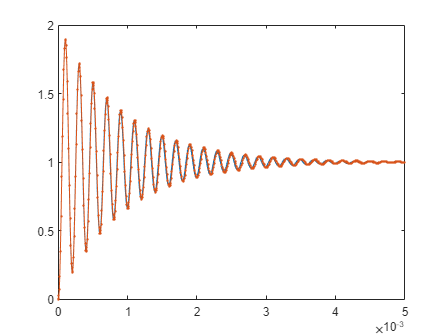

t=linspace(0,5e-3,1000);

plot(t,subs(vs),sim.t,sim.X_t(3,:),'.-')

## Circuits Non Linéaires 

### Point de fonctionnement d'un circuit Resistance - Diode en série

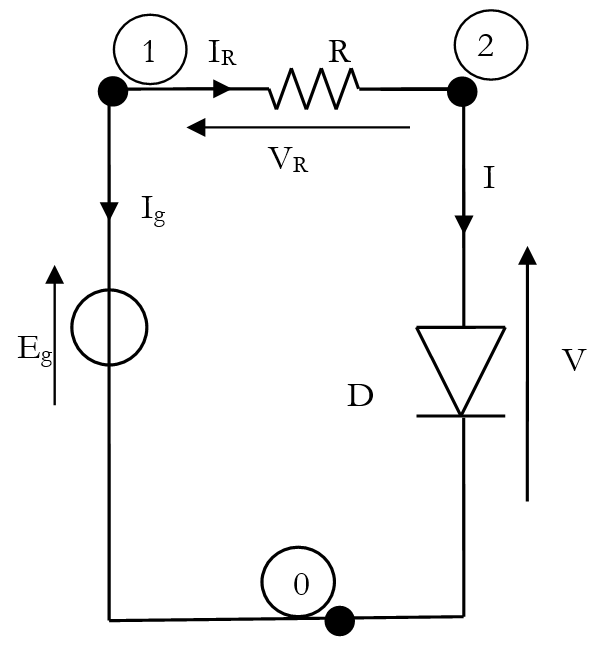

netlist={
    'V1 1 0 10'     % Générateur Eg
    'R1 1 2 1e3'   % Resistance
    'D1 2 0 1N4001'
    '.model 1N4001 D (IS1=1e-9 n1=1)'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 0 Inductor(s), 0 Capacitor(s), 1 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [3×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'I(V1)'}

sim.X

ans =    10.0000
    0.4156
   -0.0096


La tension aux bornes de la diode est 0.4156 V, le courant tranversant la diode est 9.6 mA.

### Evolution de la tension V et courant I en fonction de la tension Eg (0 - 10 V):

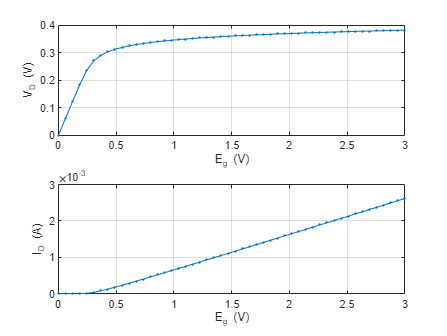

netlist={
    'V1 1 0 0'     % Générateur Eg
    'R1 1 2 1e3'   % Resistance
    'D1 2 0 1N4001'
    '.model 1N4001 D (IS1=1e-9 n1=1)'
    '.mute'
    };
V1=linspace(0,3,50);
for i=1:length(V1)
    netlist{1}=['V1 1 0 ' num2str(V1(i))]; % num2str convertit un double en string,
    %  puis on concatène les chaines de caractères
    sim=uacs(netlist);
    X=sim.X;
    VD(i)=X(2);Id(i)=-X(3);
end
subplot(2,1,1);plot(V1,VD,'.-');xlabel('E_g (V)');ylabel('V_D (V)');grid
subplot(2,1,2);plot(V1,Id,'.-');xlabel('E_g (V)');ylabel('I_D (A)');grid

### Detecteur d'enveloppe

netlist={
    'R1 2 0 1000'
    'C1 2 0 100e-9'
    'D1 1 2 1N4001'
    '.model 1N4001 D (IS1=14.11e-9 n1=1.984)'
    'V1 1 0 @(t) 5*sin(2*pi*87e3*t).*(1+0.4*sin(2*pi*1e3*t))'
    '.tran tstop=3e-3 dtmax=1e-6 initTRAN=CI'
    '.probe 1 2'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-06, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 0 Inductor(s), 1 Capacitor(s), 1 Diode(s), 0 Current Source(s), 1 Voltage Source(s) 2 electrical node(s)
Transient Simulation, t0=0, tmax=0.00299992, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

4935 time steps computed in 5.15687 seconds.


sim = struct with fields:
           X_t: [3×4935 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {2×1 cell}
      probe_id: [1 2]
         names: {'V(1)'  'V(2)'  'I(V1)'}

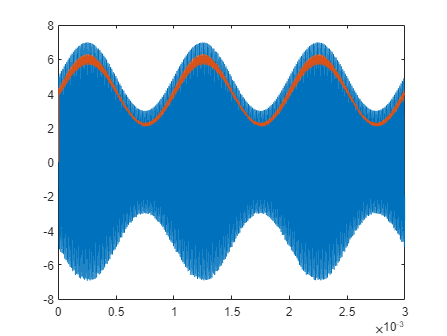

figure
plot(sim.t,sim.X_t(sim.probe_id(:),:))

## Amplificateur opérationnel

### Amplificateur Opérationnel : uA741 : Inverseur


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=1000 a=1 off=0)'
    
    '.tran tstop=2e-3 dtmax=.3e-4 initTRAN=CI'
    '.probe vg out'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=3e-05, dt_min=1e-09, dt0=1e-12
17 Resistor(s), 0 Inductor(s), 4 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00199995, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

343 time steps computed in 0.657061 seconds.


sim = struct with fields:
           X_t: [34×343 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {2×1 cell}
      probe_id: [20 9]
         names: {1×34 cell}

Les tensions définies par .probe sont :

sim.probe_name

ans = 2×1 cell array
    {'vg' }
    {'out'}

Si on souhaite visualiser les tensions 'vg' et 'out' :

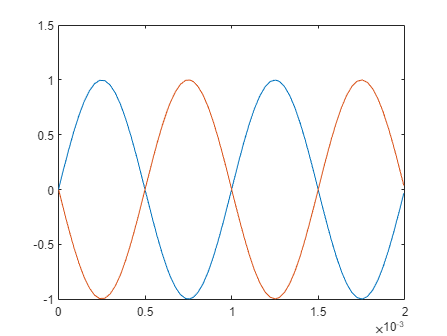

figure
plot(sim.t,sim.X_t(sim.probe_id,:))

### Amplificateur Opérationnel : uA741 : Inverseur (Saturation)


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=1000 a=15 off=0)'
    
    '.tran tstop=2e-3 dtmax=.3e-4 initTRAN=CI'
    '.probe vg out'
    '.mute'
    };
sim=uacs(netlist);

Si on souhaite visualiser les tensions 'vg' et 'out' :

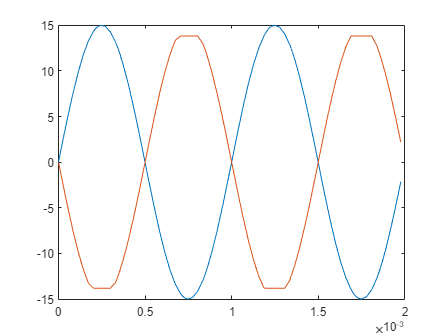

figure
plot(sim.t,sim.X_t(sim.probe_id,:))

### Amplificateur Opérationnel : uA741 : Inverseur (Slew Rate)


netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','e-','out')
    %% Circuit
    'R1 e+ 0 500'
    'R2 e- out 1000'
    'R3 e- vg 1000'
    'V1 vg 0 sin(f=100e3 a=0.1 off=0)'
    
    '.tran tstop=2e-5 dtmax=.1e-6 initTRAN=CI'
    '.probe vg out'
    '.mute'
    };
% simulation 1 avec f=100 kHz, amplitude 0.1
sim1=uacs(netlist);
% simulation 2 avec f=100 kHz, amplitude 1
netlist{5}='V1 vg 0 sin(f=100e3 a=1 off=0)';
sim2=uacs(netlist);
% simulation 3 avec f=100 kHz, amplitude 2
netlist{5}='V1 vg 0 sin(f=100e3 a=2 off=0)';
sim3=uacs(netlist);


Si on souhaite visualiser les tensions 'vg' et 'out' :

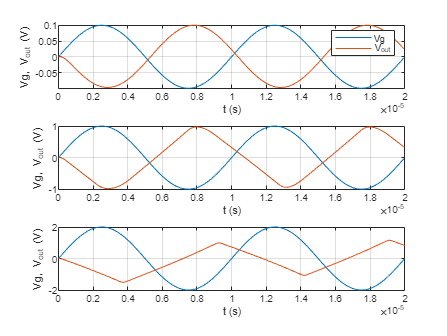

figure
subplot(3,1,1);plot(sim1.t,sim1.X_t(sim1.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid
subplot(3,1,2);plot(sim2.t,sim2.X_t(sim2.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');grid
subplot(3,1,3);plot(sim3.t,sim3.X_t(sim3.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');grid

### Amplificateur Opérationnel : uA741 : Filtre Passe Bas Salen-Key

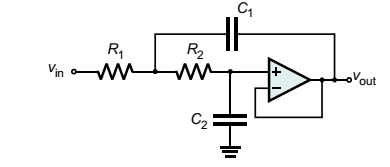

netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','out','out')
    %% Circuit
    'R1 vg A 1000'
    'R2 A e+ 1000'
    'C1 A out 63.6e-9'
    'C2 e+ 0 3.97e-9'
    'V1 vg 0 sin(f=10000 a=1 off=0)'
    
    '.tran tstop=4e-4 dtmax=1e-4 initTRAN=OP'
    '.probe vg out'
    
    };
sim=uacs(netlist);

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=0.0001, dt_min=1e-09, dt0=1e-12
16 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00039999, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale = OP
[ok]

359 time steps computed in 0.501871 seconds.


Si on souhaite visualiser les tensions 'vg' et 'out' :

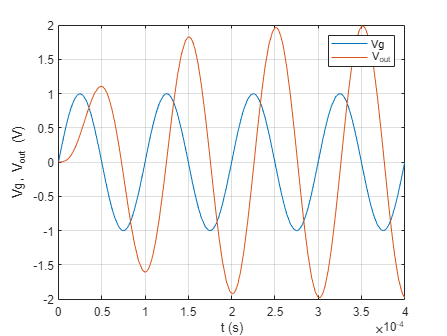

figure
plot(sim.t,sim.X_t(sim.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid

### Amplificateur Opérationnel : uA741 : Filtre Passe Bas Salen-Key, réponse à un échelon

netlist={
    %Amplificateur Opérationnel uA741
    uA741('e+','out','out')
    %% Circuit
    'R1 vg A 1000'
    'R2 A e+ 1000'
    'C1 A out 63.6e-9'
    'C2 e+ 0 3.97e-9'
    
    'V1 vg 0 1'
    
    '.tran tstop=4e-4 dtmax=1e-4 initTRAN=CI'
    '.probe vg out'
    
    };
sim=uacs(netlist);

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=0.0001, dt_min=1e-09, dt0=1e-12
16 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 10 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00039999, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

512 time steps computed in 0.851669 seconds.


Si on souhaite visualiser les tensions 'vg' et 'out' :

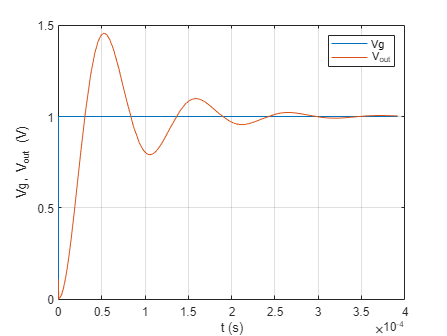

figure
plot(sim.t,sim.X_t(sim.probe_id,:));xlabel('t (s)');ylabel('Vg, V_{out} (V)');legend('Vg','V_{out}');grid

### Source de courant pour PT100

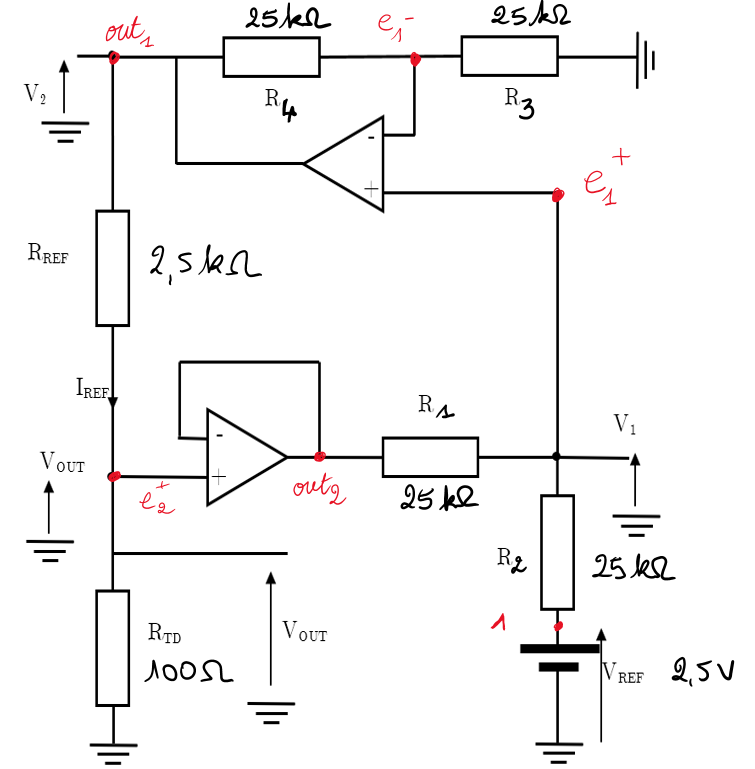

netlist={
    %Amplificateur Opérationnel uA741 1
    uA741('e1+','e1-','out1')
    %Amplificateur Opérationnel uA741 2
    uA741('e2+','out2','out2')
    %% Circuit R1 R2 R3 Rref Vref
    'R1 out2 e1+ 25e3'
    'R2 e1+ 1 25e3'
    'R3 e1- 0 25e3'
    'R4 e1- out1 25e3'
    'Vvref 1 0 2.5'
    'Rref out1 e2+ 2.5e3'
    % Resistance Thermal detector (RTD) PT100
    'Rrtd e2+ 0 100'
    '.OP'    % Simulation statique du point de fonctionnement DC
    '.probe e2+'
    
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=, dt_min=1e-09, dt0=1e-12
34 Resistor(s), 0 Inductor(s), 8 Capacitor(s), 10 Diode(s), 6 Current Source(s), 19 Voltage Source(s) 42 electrical node(s)
in.t and in.t_bounds not provided ... OP solver
Calcul point de Fonctionnement
[ok]


sim = struct with fields:
             X: [65×1 double]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {'e2+'}
      probe_id: 12
         names: {1×65 cell}

fprintf('Tension Vout = %g Volts \n',sim.X(sim.probe_id))

Tension Vout = 0.100073 Volts 


Avec des aplificateurs opérationnels idéaux, on obtient que Iref=1 mA. La tension Vout divisée par 1mA donne la valeur de la résistance de la RTD, et donc de la température avec Rrtd=100(1+0.00385 T). Le modèle de l'AOP UA741 dans uacs prend en compte la tension d'offset et les courant d'entrée (courants de polarisation), ceci introduit un écart sur le courant Iref traversant la RTD.

Ttheo=0;Rtheo=100*(1+.00385*Ttheo)

Rtheo = 100

Rmes=sim.X(sim.probe_id)/1e-3;
fprintf('Résistance mesurée : %g ohms, erreur relative %2.3f %% par rapport à la valeur théorique %g ohms\n',Rmes,abs(Rmes-Rtheo)/Rtheo*100, Rtheo)

Résistance mesurée : 100.073 ohms, erreur relative 0.073 % par rapport à la valeur théorique 100 ohms


Tmes=(Rmes/100-1)/0.00385;
fprintf('Temperature mesurée %g °C , valeur théorique %g °C\n',Tmes,Ttheo)

Temperature mesurée 0.190503 °C , valeur théorique 0 °C


## Oscillateur à réseau déphaseur (pont de Wien)

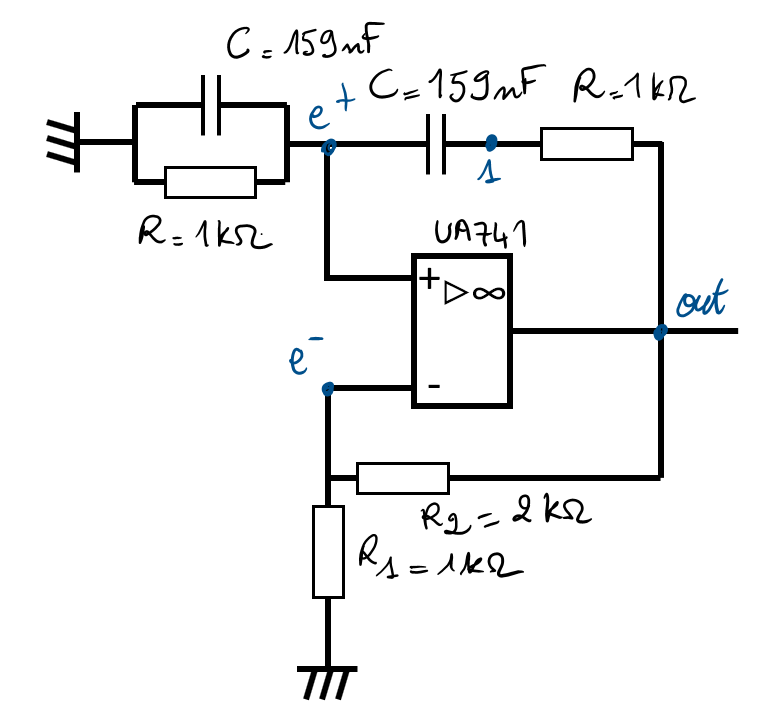

La fréquence d'oscillation est $\frac{1}{2\pi RC}$. L'amplitude des oscillations est réglé par la tension initiale sur la capacité entre e+ et 1. L'amplitude est égale à $3\times v_{c0}$ avec $v_{C0}=\frac{1}{3}$ dans cet exemple.

netlist={
    'R1 0 e+ 1000'
    'C1 0 e+ 159e-9'
    'C2 e+ 1 159e-9 IC=1/3'
    'R2 1 out 1000'
    uA741('e+','e-','out')
    'R3 0 e- 1000'
    'R4 e- out 2000'
    '.tran tstop=10e-3 dtmax=1e-5 initTRAN=CI'
    '.probe out e+ e-'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
18 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 9 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.00999975, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

1230 time steps computed in 1.55041 seconds.


sim = struct with fields:
           X_t: [33×1230 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {3×1 cell}
      probe_id: [10 6 7]
         names: {1×33 cell}

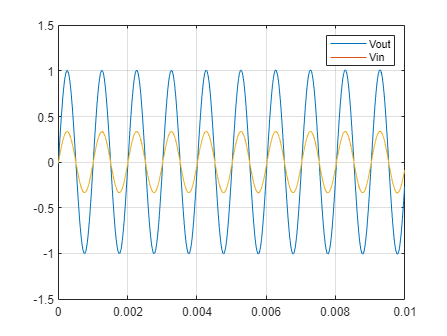

plot(sim.t,sim.X_t(sim.probe_id(1:3),:))
grid
legend('Vout','Vin')

## Electronique de puissance

### Electronique de puissance - Hacheur Série

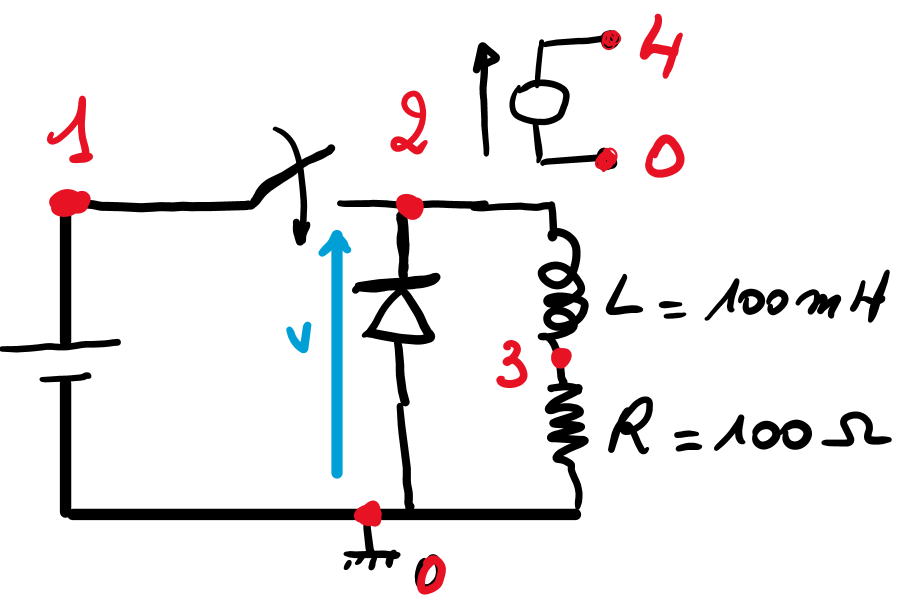

L'interrupteur commandé S est inséré entre 1 et 2. Il est commandé par la tension vc=v(4)-v(0). Si vc=0, l'interrupteur est équivalent à 1e6 ohms, si vc>0.5 il est équivalent à 1 ohm.

netlist={
    'L1 2 3 100e-3'
    'R1 3 0 100'
    'D1 0 2 1N4001'
    '.model D 1N4001 (IS1=14.11e-9 n1=1.984)' % General rectifier diode 1N4001
    'S1 1 2 4 0 1e6 1'   % interrupteur commandé
    'V1 1 0 10'
    'V2 4 0 @(t) double(sin(2*pi*1e3*t)>0)' % générateur de commande de l'interrupteur commandé
    '.tran tstop=5e-3 dtmax=1e-5 initTRAN=CI'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 1 Inductor(s), 0 Capacitor(s), 1 Diode(s), 0 Current Source(s), 2 Voltage Source(s) 4 electrical node(s)
Transient Simulation, t0=0, tmax=0.00499987, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

517 time steps computed in 0.437154 seconds.


sim = struct with fields:
           X_t: [6×517 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 3.0000e-09 6.9921e-09 1.4976e-08 3.0945e-08 6.2881e-08 1.2675e-07 2.5450e-07 5.1000e-07 1.0210e-06 2.0430e-06 4.0869e-06 8.1748e-06 1.6351e-05 2.6351e-05 3.6351e-05 4.6351e-05 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'V(3)'  'V(4)'  'I(V1)'  'I(V2)'}

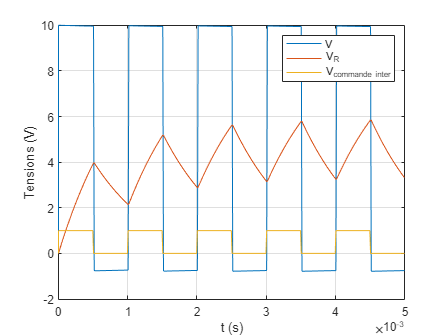

figure
plot(sim.t,sim.X_t([2 3 4],:))
xlabel('t (s)');ylabel('Tensions (V)');legend('V','V_{R}','V_{commande inter}');grid

### Electronique de puissance Hacheur 2 Quadrants

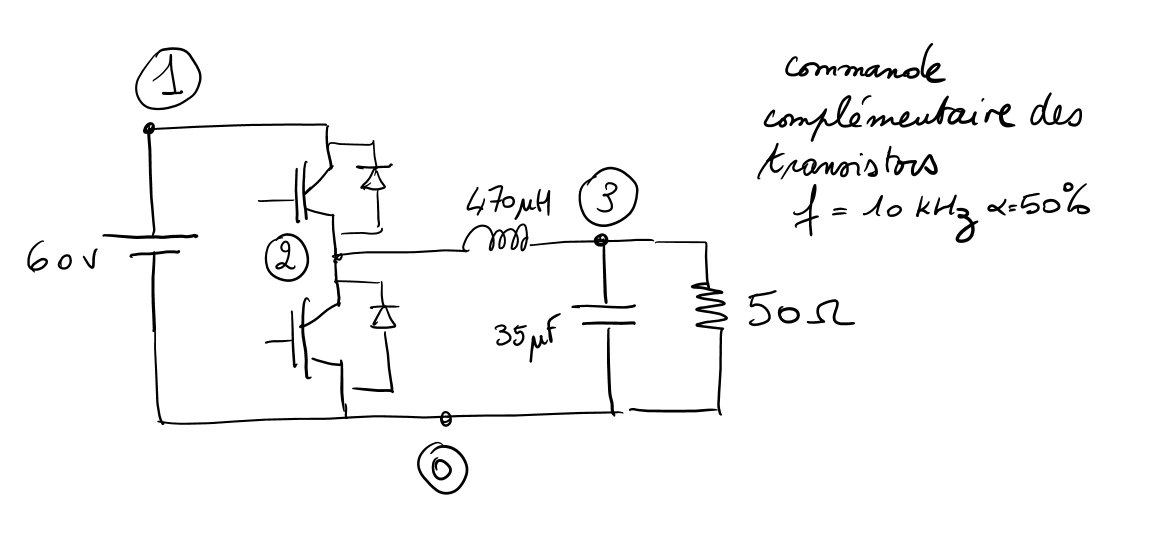

netlist={
    'L1 2 3 470e-6 IC=0.6'
    'R1 3 0 50'
    'D1 0 2 1N4001'
    'D2 2 1 1N4001'
    'C1 3 0 35e-6 IC=30'
    '.model D 1N4001 (IS1=14.11e-9 n1=1.984)' % General rectifier diode 1N4001
    'S1 1 2 4 0 1e7 .1'   % interrupteur commandé
    'S2 2 0 4 0 .1 1e7'   % interrupteur commandé
    'V1 1 0 60'
    'V2 4 0 @(t) (sin(2*pi*10e3*t)>0)' % générateur de commande des interrupteurs commandés
    '.tran tstop=50e-4 dtmax=1e-3 initTRAN=CI'
    '.force_t sort([(0.5e-4:0.5e-4:50e-4)-1e-7 (0.5e-4:0.5e-4:50e-4)+1e-7])'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=0.001, dt_min=1e-09, dt0=1e-12
1 Resistor(s), 1 Inductor(s), 1 Capacitor(s), 2 Diode(s), 0 Current Source(s), 2 Voltage Source(s) 4 electrical node(s)
Transient Simulation, t0=0, tmax=0.00499987, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

1329 time steps computed in 5.14604 seconds.


sim = struct with fields:
           X_t: [6×1329 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 3.0040e-09 7.0040e-09 1.5004e-08 3.1004e-08 6.3004e-08 1.2700e-07 2.5500e-07 5.1100e-07 1.0230e-06 2.0470e-06 4.0950e-06 8.1910e-06 1.6383e-05 3.2767e-05 4.9900e-05 5.0100e-05 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {}
      probe_id: []
         names: {'V(1)'  'V(2)'  'V(3)'  'V(4)'  'I(V1)'  'I(V2)'}

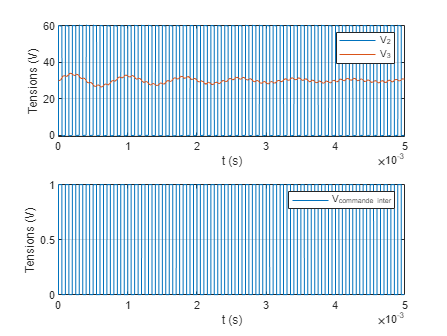

figure
subplot(2,1,1)
plot(sim.t,sim.X_t(2:3,:))
xlabel('t (s)');ylabel('Tensions (V)');legend('V_2','V_3');grid
subplot(2,1,2)
plot(sim.t,sim.X_t(4,:))
xlabel('t (s)');ylabel('Tensions (V)');legend('V_{commande inter}');grid

## Oscillateur à réseau déphaseur (pont de Wien)

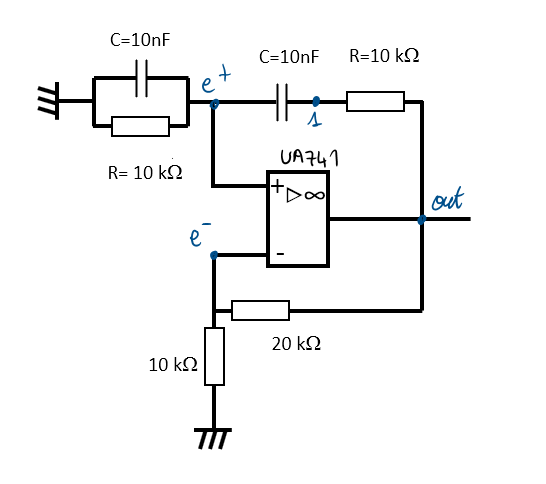

La fréquence d'oscillation est $\frac{1}{2\pi RC} \approx 1.59\ \rm {kHz}$. L'amplitude des oscillations est réglé par la tension initiale sur la capacité entre e+ et 1. L'amplitude est égale à $3\times v_{c0}$ avec $v_{C0}=\frac{1}{3}$ dans cet exemple.

netlist={
    'R1 0 e+ 10e3'
    'C1 0 e+ 10e-9'
    'C2 e+ 1 10e-9 IC=1/3'
    'R2 1 out 10e3'
    uA741('e+','e-','out')
    'R3 0 e- 10e3'
    'R4 e- out 20e3'
    '.tran tstop=20e-3 dtmax=1e-5 initTRAN=CI'
    '.probe out e+ e-'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=1e-05, dt_min=1e-09, dt0=1e-12
18 Resistor(s), 0 Inductor(s), 6 Capacitor(s), 5 Diode(s), 3 Current Source(s), 9 Voltage Source(s) 22 electrical node(s)
Transient Simulation, t0=0, tmax=0.0199995, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]

2197 time steps computed in 2.77033 seconds.


sim = struct with fields:
           X_t: [33×2197 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {3×1 cell}
      probe_id: [10 6 7]
         names: {1×33 cell}

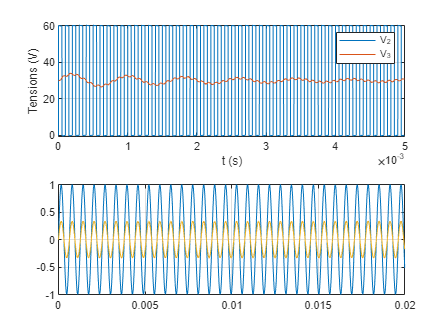

plot(sim.t,sim.X_t(sim.probe_id(1:3),:))
grid

## Oscillateur à réseau déphaseur (pont de Wien) avec controle automatique de l'amplitude

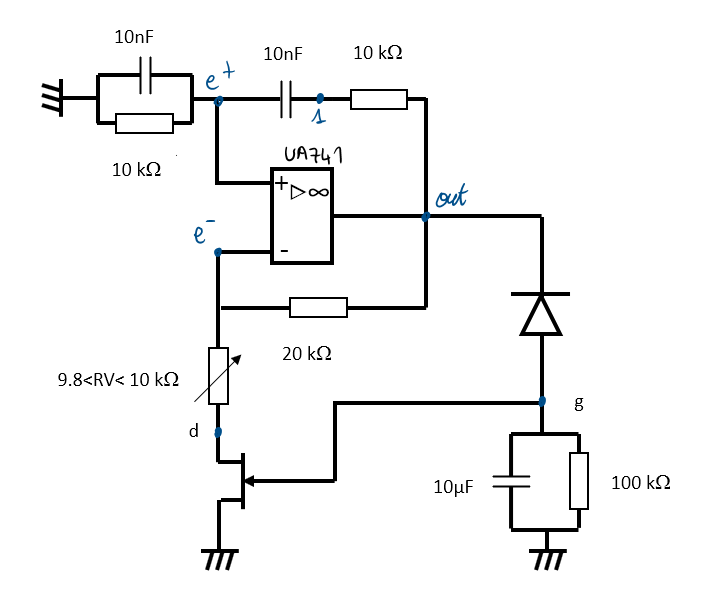

La fréquence d'oscillation est $\frac{1}{2\pi RC} \approx 1.59\ \rm {kHz}$ . L'amplitude des oscillations est est obtenue par un detecteur crête, le potentiel du noeud g est l'image de l'amplitude (valeur négative). Pour le maintien des oscillations, la résistance RV + la résistance équivalente du JFET doit etre égale à $10\,k\Omega$. La résistance équivalente du JFET en fonction de $V_{GS}$ est donnée par $R_{DS}=\frac{R_0}{1-\frac{V_{GS}}{V_p}}$ avec $R_0=100\,\Omega$ et $V_p=4\,V$:

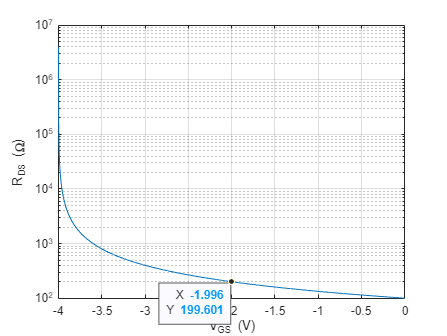

vgs=-4:.0001:0;figure;figure;semilogy(vgs,100./(1-vgs/-4));
xlabel('V_{GS} (V)');ylabel('R_{DS} (\Omega)');grid
ax = gca;
chart = ax.Children(1);
datatip(chart,-1.996,199.6,'Location','southwest');

Si $RV=9.8\,k\Omega$, il faut que la resistance équivalente du JFET soit égale à $200\,\Omega$pour que la somme fasse $10\,k\Omega$, ce qui implique que $V_{GS}=-2V$. L'amplitude de $V_{out}$ est donc légerement supérieure à 2V (ceci est dû à la chute de tension dans la diode quand elle est passante). En changeant la résistance variable RV, on change l'amplitude des oscilations.

netlist={
    'R1 e+ 0 10e3'
    'C1 0 e+ 10e-9'
    'C2 e+ 1 10e-9'
    'R2 1 out 10e3'
    uA741('e+','e-','out')
    'R3 d e- 9.85e3'
    'R4 e- out 20e3'
    'R1 g 0 100e3'
    'C3 g 0 10e-6'
    'D1 g out 1N34A'
    'B1 d 0 d g 1'
    '.fun 1{@(vd,vg) fun_jfet(vd,vg)}'
    '.model 1N34A D (IS1=2e-7 n1=1.3)'
    '.tran tstop=180e-3 dtmax=8e-5 initTRAN=CI'
    '.probe out e+ g'
    };
sim=uacs(netlist)

Analog Circuit Simulator v2 (c)Frederic Martinez
max time steps =200000 TolR=0.001 TolA=1e-12 TolR_NR=0.001 TolA_NR=1e-12 maxIterNR=5000 dt_max=8e-05, dt_min=1e-09, dt0=1e-12
19 Resistor(s), 0 Inductor(s), 7 Capacitor(s), 6 Diode(s), 3 Current Source(s), 9 Voltage Source(s) 24 electrical node(s)
Transient Simulation, t0=0, tmax=0.179995, with Trapezoidal dicretization and  automatic time step control.
Solution initiale @ t=0 // Solution initiale Sources à 0 et  IC_C  IC_L
[ok]


8811 time steps computed in 13.7885 seconds.


sim = struct with fields:
           X_t: [35×8811 double]
             t: [0 1.0000e-12 2.0000e-12 3.0000e-12 4.0000e-12 1.0040e-09 2.0040e-09 3.0040e-09 4.0040e-09 5.0040e-09 6.0040e-09 7.0040e-09 8.0040e-09 9.0040e-09 1.0004e-08 1.1004e-08 1.2004e-08 1.3004e-08 1.4004e-08 1.5004e-08 1.6004e-08 1.7004e-08 … ]
            in: [1×1 struct]
    out_parser: [1×1 struct]
    probe_name: {3×1 cell}
      probe_id: [12 7 9]
         names: {1×35 cell}

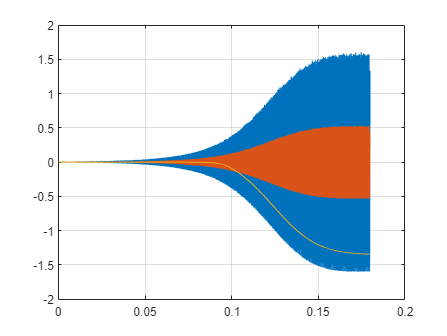

figure
plot(sim.t,sim.X_t(sim.probe_id(1:3),:))
grid